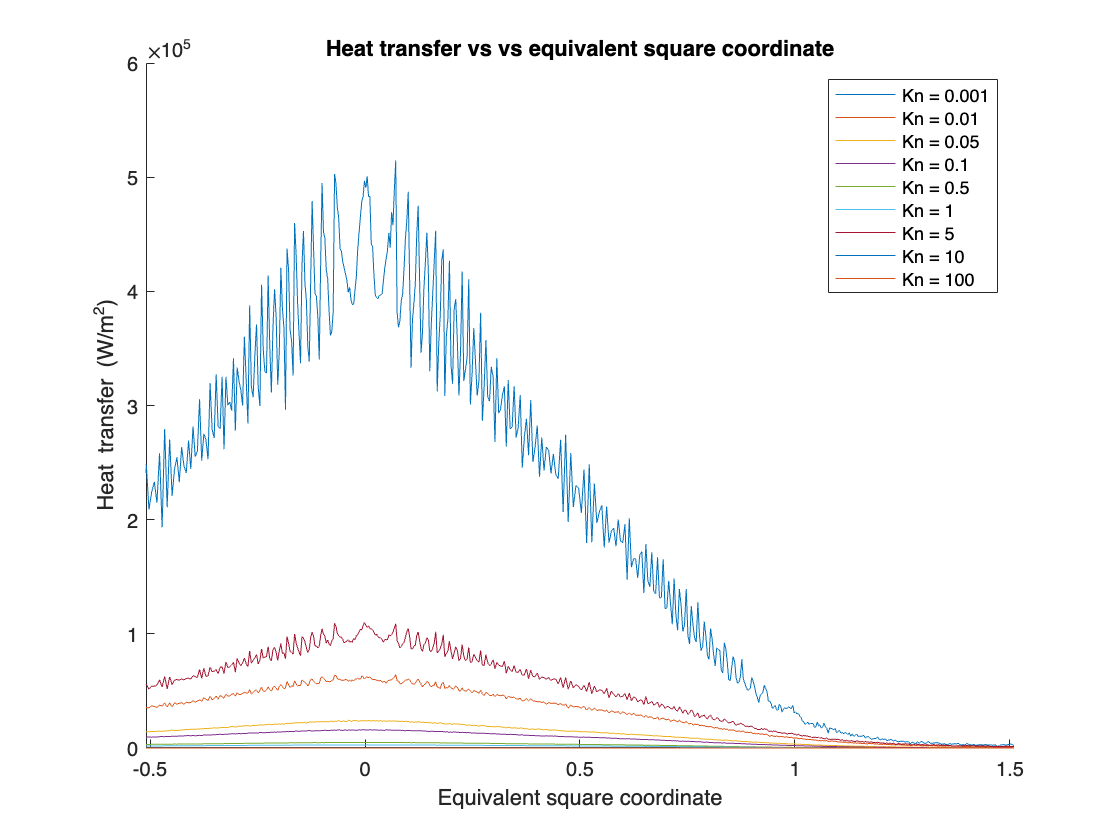

clear

sp=249;
u=1655;
cp=1.4;
tw=300;
t0=273;
H0=cp*t0+u^2/2;
hw=cp*tw;

D0001 = readmatrix('./circleKn_results/kn0.001.txt');
D0001 = sortrows(D0001(8:1007,1:10),1);
D0001(:,11) = D0001(:,10)./mean(D0001(sp-5:sp+5,10));
rho001=1.727e-3;
D0001(:,12) = D0001(:,10)./(rho001 * u * (H0 - hw));
D0001(:,13) = D0001(:,12)./mean(D0001(sp-5:sp+5,12));

D001 = readmatrix('./circleKn_results/kn0.01.txt');
D001 = sortrows(D001(8:1007,1:10),1);
D001(:,11) = D001(:,10)./mean(D001(sp-5:sp+5,10));
rho001=1.727e-4;
D001(:,12) = D001(:,10)./(rho001 * u * (H0 - hw));
D001(:,13) = D001(:,12)./mean(D001(sp-5:sp+5,12));

D005 = readmatrix('./circleKn_results/kn0.05.txt');
D005 = sortrows(D005(8:1007,1:10),1);
D005(:,11) = D005(:,10)./mean(D005(sp-5:sp+5,10));
rho005=3.454e-5;
D005(:,12) = D005(:,10)./(rho005 * u * (H0 - hw));
D005(:,13) = D005(:,12)./mean(D005(sp-5:sp+5,12));

D01 = readmatrix('./circleKn_results/kn0.1.txt');
D01 = sortrows(D01(8:1007,1:10),1);
D01(:,11) = D01(:,10)./mean(D01(sp-5:sp+5,10));
rho01=1.727e-5;
D01(:,12) = D01(:,10)./(rho01 * u * (H0 - hw));
D01(:,13) = D01(:,12)./mean(D01(sp-5:sp+5,12));

D05 = readmatrix('./circleKn_results/kn0.5.txt');
D05 = sortrows(D05(8:1007,1:10),1);
D05(:,11) = D05(:,10)./mean(D05(sp-5:sp+5,10));
rho05=3.454e-6;
D05(:,12) = D05(:,10)./(rho05 * u * (H0 - hw));
D05(:,13) = D05(:,12)./mean(D05(sp-5:sp+5,12));

D1 = readmatrix('./circleKn_results/kn1.txt');
D1 = sortrows(D1(8:1007,1:10),1);
D1(:,11) = D1(:,10)./mean(D1(sp-5:sp+5,10));
rho1=1.727e-6;
D1(:,12) = D1(:,10)./(rho1 * u * (H0 - hw));
D1(:,13) = D1(:,12)./mean(D1(sp-5:sp+5,12));

D5 = readmatrix('./circleKn_results/kn5.txt');
D5 = sortrows(D5(8:1007,1:10),1);
D5(:,11) = D5(:,10)./mean(D5(sp-5:sp+5,10));
rho5=3.454e-7;
D5(:,12) = D5(:,10)./(rho5 * u * (H0 - hw));
D5(:,13) = D5(:,12)./mean(D5(sp-5:sp+5,12));

D10 = readmatrix('./circleKn_results/kn10.txt');
D10 = sortrows(D10(8:1007,1:10),1);
D10(:,11) = D10(:,10)./mean(D10(sp-5:sp+5,10));
rho10=1.727e-7;
D10(:,12) = D10(:,10)./(rho10 * u * (H0 - hw));
D10(:,13) = D10(:,12)./mean(D10(sp-5:sp+5,12));

D100 = readmatrix('./circleKn_results/kn100.txt');
D100 = sortrows(D100(8:1007,1:10),1);
D100(:,11) = D100(:,10)./mean(D100(sp-5:sp+5,10));
rho10=1.727e-8;
D100(:,12) = D100(:,10)./(rho10 * u * (H0 - hw));
D100(:,13) = D100(:,12)./mean(D100(sp-5:sp+5,12));

coords=coords('./circleKn_results/circle.txt');

fig1=figure;
hold on
plot(coords(:,2),D0001(:,10))
plot(coords(:,2),D001(:,10))
plot(coords(:,2),D005(:,10))
plot(coords(:,2),D01(:,10))
plot(coords(:,2),D05(:,10))
plot(coords(:,2),D1(:,10))
plot(coords(:,2),D5(:,10))
plot(coords(:,2),D10(:,10))
plot(coords(:,2),D100(:,10))
legend('Kn = 0.001','Kn = 0.01','Kn = 0.05','Kn = 0.1',...
       'Kn = 0.5','Kn = 1','Kn = 5','Kn = 10','Kn = 100')
xlabel('Equivalent square coordinate')
ylabel('Heat transfer (W/m^2)')
xlim([-0.51, 1.51])
title('Heat transfer vs vs equivalent square coordinate')

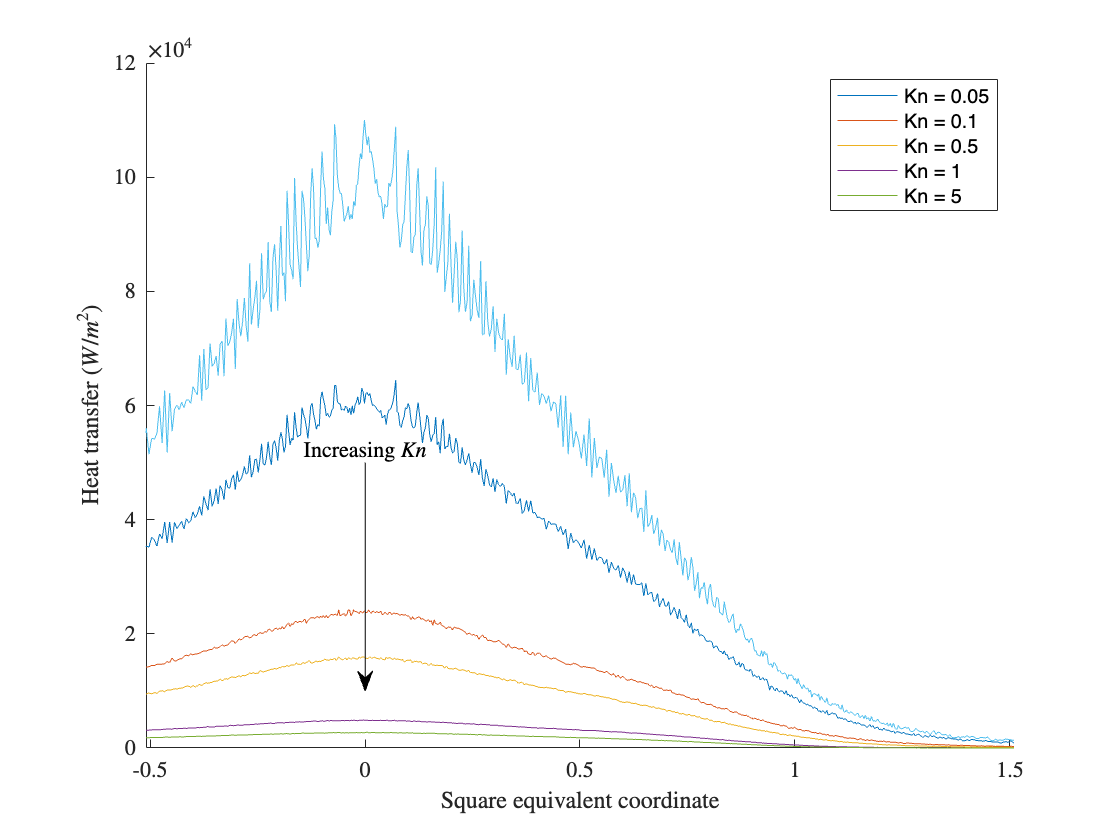


fig2=figure;
hold on
plot(coords(:,2),D001(:,10))
plot(coords(:,2),D005(:,10))
plot(coords(:,2),D01(:,10))
plot(coords(:,2),D05(:,10))
plot(coords(:,2),D1(:,10))
plot(coords(:,2),D5(:,10))
legend('Kn = 0.05','Kn = 0.1',...
       'Kn = 0.5','Kn = 1','Kn = 5')
xlabel('Square equivalent coordinate','interpreter','latex','FontSize',11)
ylabel('Heat transfer ($W / m^2$)','interpreter','latex','FontSize',11)
set(gca,'TickLabelInterpreter','latex','FontSize',11)
xlim([-0.51, 1.51])
%ylim([0,12e4])
anArrow = annotation('textarrow','String','Increasing $Kn$','interpreter','latex','FontSize',11) ;
anArrow.Parent = gca;  
anArrow.Position = [0, 5e4, 0, -4e4] ;
exportgraphics(fig2,'../Images/4. Results/Circle Kn/htsec.pdf','ContentType','vector');

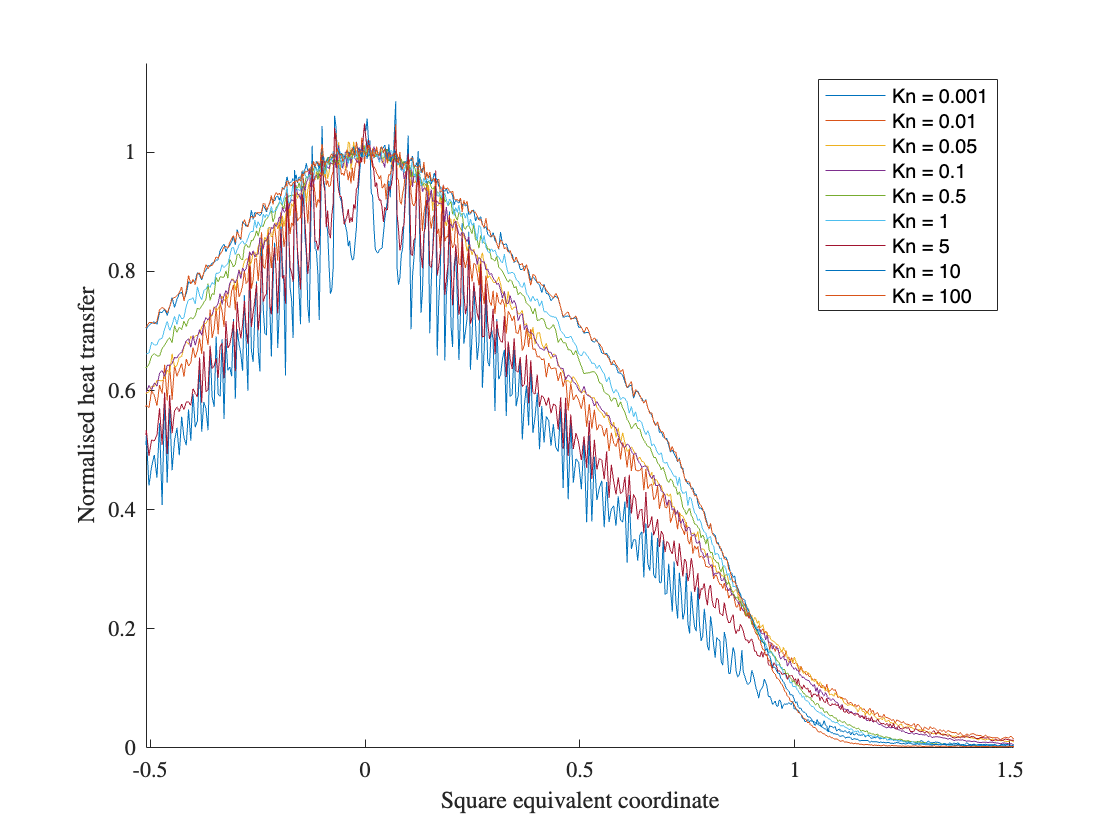



fig3=figure;
hold on
plot(coords(:,2),D0001(:,11))
plot(coords(:,2),D001(:,11))
plot(coords(:,2),D005(:,11))
plot(coords(:,2),D01(:,11))
plot(coords(:,2),D05(:,11))
plot(coords(:,2),D1(:,11))
plot(coords(:,2),D5(:,11))
plot(coords(:,2),D10(:,11))
plot(coords(:,2),D100(:,11))
legend('Kn = 0.001','Kn = 0.01','Kn = 0.05','Kn = 0.1',...
       'Kn = 0.5','Kn = 1','Kn = 5','Kn = 10','Kn = 100')
xlabel('Square equivalent coordinate','interpreter','latex','FontSize',11)
ylabel('Normalised heat transfer','interpreter','latex','FontSize',11)
set(gca,'TickLabelInterpreter','latex','FontSize',11)
xlim([-0.51, 1.51])
ylim([0,1.15])
exportgraphics(fig3,'../Images/4. Results/Circle Kn/nhtsec.pdf','ContentType','vector');

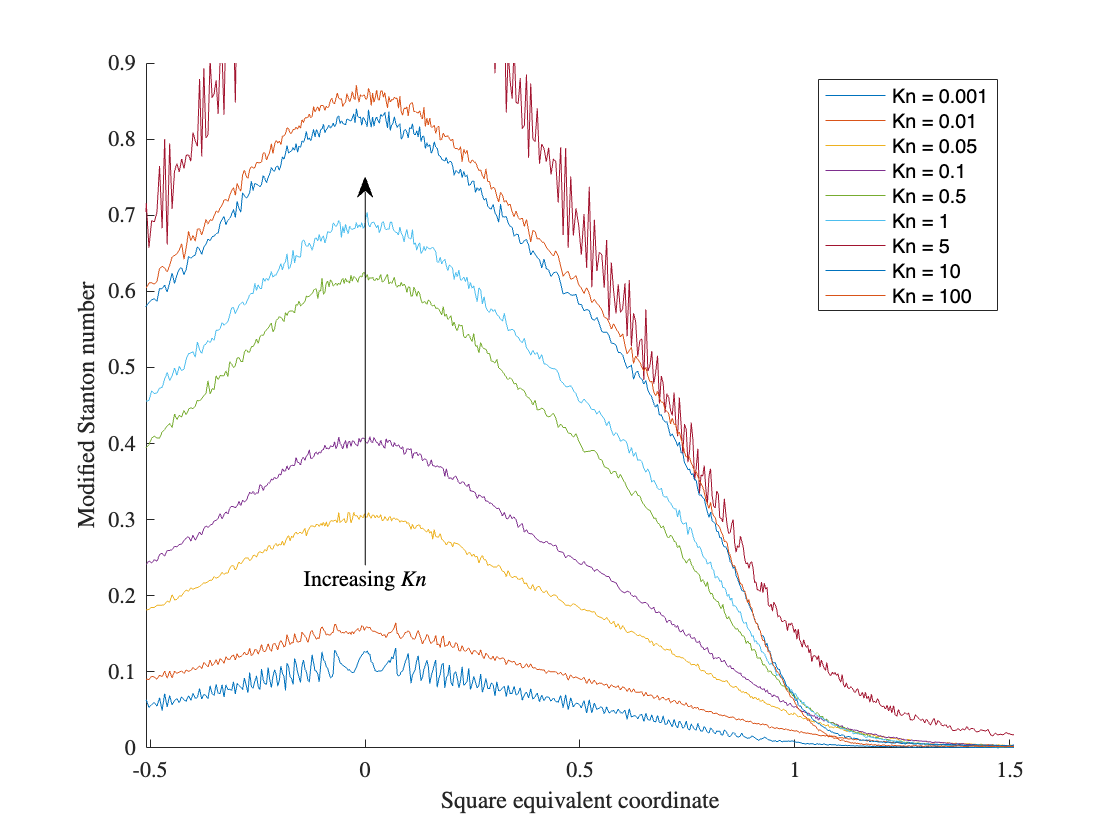


fig4=figure;
hold on
plot(coords(:,2),D0001(:,12))
plot(coords(:,2),D001(:,12))
plot(coords(:,2),D005(:,12))
plot(coords(:,2),D01(:,12))
plot(coords(:,2),D05(:,12))
plot(coords(:,2),D1(:,12))
plot(coords(:,2),D5(:,12))
plot(coords(:,2),D10(:,12))
plot(coords(:,2),D100(:,12))
legend('Kn = 0.001','Kn = 0.01','Kn = 0.05','Kn = 0.1',...
       'Kn = 0.5','Kn = 1','Kn = 5','Kn = 10','Kn = 100')
xlabel('Square equivalent coordinate','interpreter','latex','FontSize',11)
ylabel('Modified Stanton number','interpreter','latex','FontSize',11)
set(gca,'TickLabelInterpreter','latex','FontSize',11)
xlim([-0.51, 1.51])
ylim([0,0.9])
anArrow = annotation('textarrow','String','Increasing $Kn$','interpreter','latex','FontSize',11) ;
anArrow.Parent = gca;  
anArrow.Position = [0, 0.24, 0, 0.51] ;
exportgraphics(fig4,'../Images/4. Results/Circle Kn/stsec.pdf','ContentType','vector');

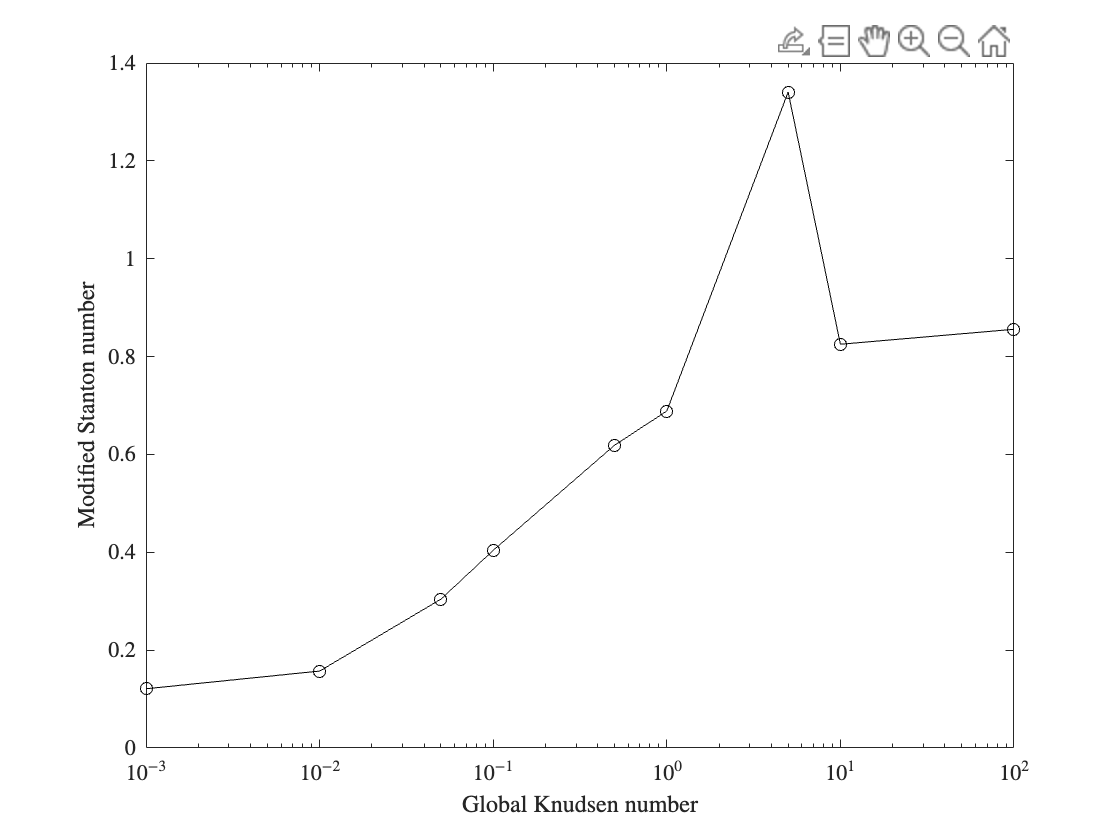


spstanton=[mean(D0001(sp-5:sp+5,12)),mean(D001(sp-5:sp+5,12)),mean(D005(sp-5:sp+5,12)),...
           mean(D01(sp-5:sp+5,12)),mean(D05(sp-5:sp+5,12)),mean(D1(sp-5:sp+5,12)),...
           mean(D5(sp-5:sp+5,12)),mean(D10(sp-5:sp+5,12)),mean(D100(sp-5:sp+5,12))];

globalKn=[0.001,0.01, 0.05, 0.1, 0.5, 1, 5, 10, 100];

fig5=figure;
semilogx(globalKn,spstanton,'o-k')
xlabel('Global Knudsen number','interpreter','latex','FontSize',11)
ylabel('Modified Stanton number','interpreter','latex','FontSize',11)
set(gca,'TickLabelInterpreter','latex','FontSize',11)
data = readmatrix('./kn_results/data.txt');
exportgraphics(fig5,'../Images/4. Results/Circle Kn/stkn.pdf','ContentType','vector');